Laptop Data Units

- Acceleration: m/s^2

- Orientation: Degrees

- Angular Velocity: degrees/s

- Forces: lb

Phone Data Units

- Acceleration: m/s^2

- Orientation: Degrees

- Angular Velocity: rad/s

Load swingDAQ data

% Load Data
load swingdata.mat 

% If you want to write to excel, uncomment
% writetable(acquiredData, "swingdata.xlsx");

% Remove possible spikes from LC1 to LC6
LC1 = removespikes(acquiredData.LC1);
LC2 = removespikes(acquiredData.LC2);
LC3 = removespikes(acquiredData.LC3);
LC4 = removespikes(acquiredData.LC4);
LC5 = removespikes(acquiredData.LC5);
LC6 = removespikes(acquiredData.LC6);

Load Phone Data


% Load Data
load phonedata.mat

Acceleration = renamevars(Acceleration, ["X","Y","Z"],...
["AccelX","AccelY","AccelZ"]);
AngularVelocity = renamevars(AngularVelocity, ["X","Y","Z"],...
["OmegaY","OmegaX","OmegaZ"]);
Orientation = renamevars(Orientation, ["X","Y","Z"],...
["OrientX","OrientY","OrientZ"]); % Note the switch in order
% because of naming convention in
% MATLAB Mobile/iphone

phoneData = synchronize(Acceleration, AngularVelocity, Orientation, ...
'union', 'linear'); % Merge the three timetables into one
% If want to write to Excel, uncomment
% writetimetable(phoneData,"phoneData.xlsx");

% find index of each peak
%[~, idx1] = max(acquiredData.OrientY);
%[~, idx2] = max(phoneData.OrientY);
%toffset = acquiredData.Time(idx1) - phoneData.Time(idx2); % offset between swing and phone data obtained
% by comparing peaks in OrientY

toffset = -17.677

toffset = -17.6770

disp(toffset);

  -17.6770



t_phone = second(phoneData.Timestamp,"secondofday");
t_phone = t_phone - t_phone(1)-toffset;
clear Acceleration AngularVelocity Orientation

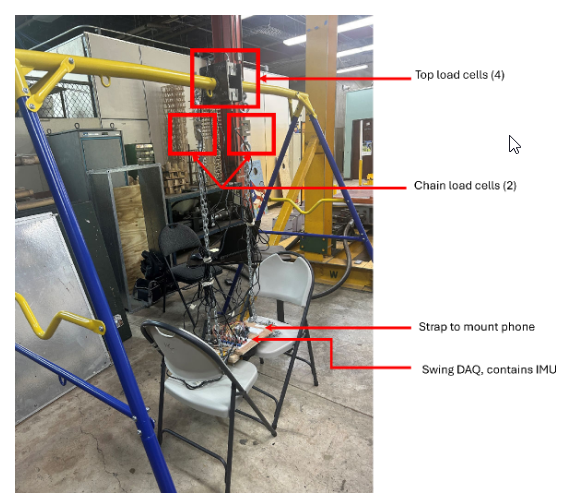

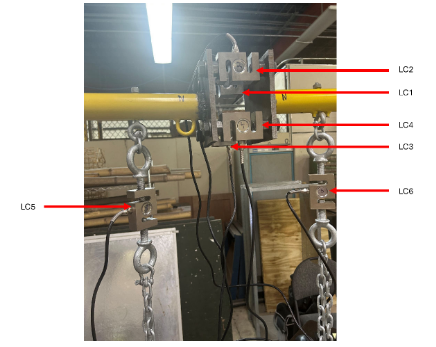

Purposes:

- IMU - Measure acceleration and angular velocity. Estimate orientation.

- LC5 & LC6 - Measure Chain Tension.

- LC1 through LC4 - Measure Beam Bending Moment.

What we need to measure from our datasets:

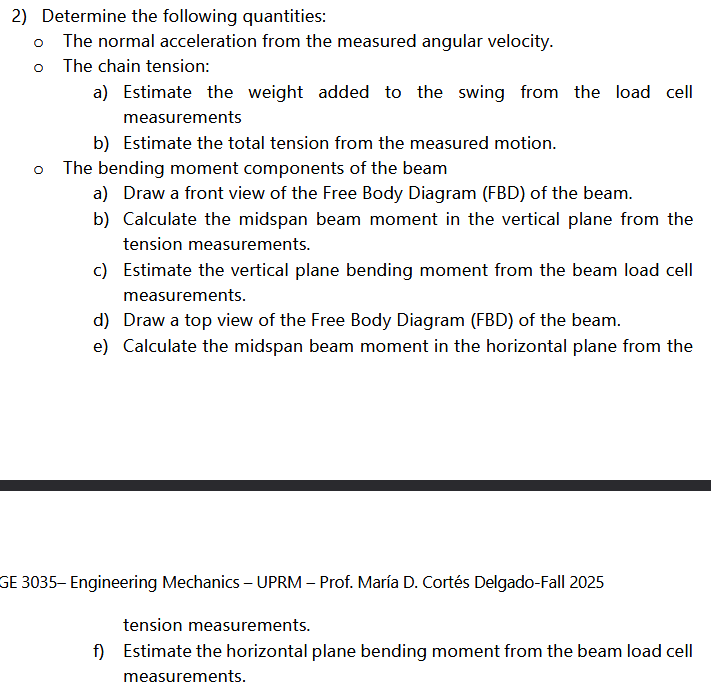

Calculate Normal Acceleration

% Calculate with data from both laptop and phone 
% Radius is equal to length of chains = 60 inches
r = 1.524; % 60 inches -> 1.524 meters

acquiredData.OmegaX = acquiredData.OmegaX * (pi/180);
acquiredData.OmegaY = acquiredData.OmegaY * (pi/180);
acquiredData.OmegaZ = acquiredData.OmegaZ * (pi/180);
mag_omega_laptop = sqrt((acquiredData.OmegaX.^2) + (acquiredData.OmegaY.^2) + (acquiredData.OmegaZ.^2));
a_normal_laptop = (mag_omega_laptop.^2) * r;
avg_a_normal_laptop = mean(a_normal_laptop);
disp("Normal Acceleration using Laptop Data")

Normal Acceleration using Laptop Data


disp(avg_a_normal_laptop);

    0.0716




mag_omega_phone = sqrt(phoneData.OmegaX.^2 + phoneData.OmegaY.^2 + phoneData.OmegaZ.^2);
a_normal_phone = (mag_omega_phone.^2) * r;
avg_a_normal_phone = mean(a_normal_phone);
disp("Normal Acceleration using Phone Data")

Normal Acceleration using Phone Data


disp(avg_a_normal_phone);

    0.0746



Calculate Weight and Total Tension